# Qs1

Poles at $-2,\pm2j$:- 2 poles on imaginary axis and one pole in LHP, so it is marginally stable, as seen from the impulse response of the transfer function.

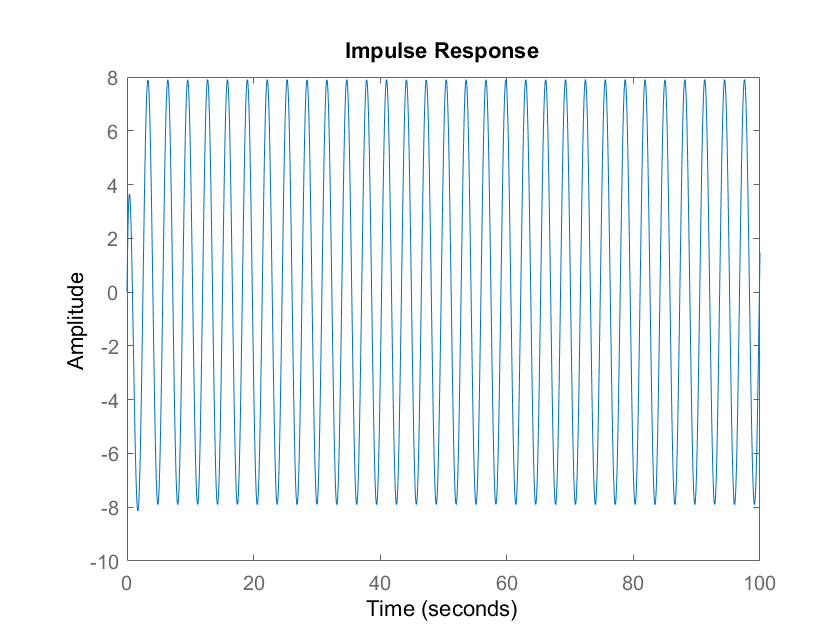

tf1=zpk(1,[-2,2i,-2i],20);

impulse(tf1,100)

# QS. 2

Characteristic equation,


$$2s^4+s^3+3s^2+5s+10=0$$


y1=rhc([2,1,3,5,10],1);


 Routh-Hurwitz Table:


rhTable =     2.0000    3.0000   10.0000
    1.0000    5.0000         0
   -7.0000   10.0000         0
    6.4286         0         0
   10.0000         0         0


if y1==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is unstable 


# QS. 3

Characteristic equation,


$$s^4+s^3+2s^2+2s+3=0$$


y2=rhc([1,1,2,2,3],1);


 Routh-Hurwitz Table:


rhTable = 	1.0e+04 *

    0.0001    0.0002    0.0003
    0.0001    0.0002         0
    0.0000    0.0003         0
   -2.9998         0         0
    0.0003         0         0


if y2==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is unstable 


# QS. 4

Characteristic equation,


$$s^5+4s^4+8s^3+8s^2+7s+4=0$$


y3=rhc([1,4,8,8,7,4],1);


 Routh-Hurwitz Table:


rhTable =     1.0000    8.0000    7.0000
    4.0000    8.0000    4.0000
    6.0000    6.0000         0
    4.0000    4.0000         0
    0.0001         0         0
    4.0000         0         0



if y3==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is stable 


# QS. 5

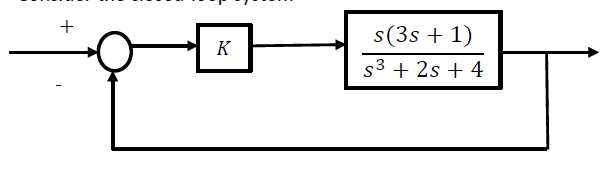

For $K\geq-1+\sqrt{\frac{7}{3}}$ the system is stable

For $K=-1+\sqrt{\frac{7}{3}}$ it is marginally stable. 

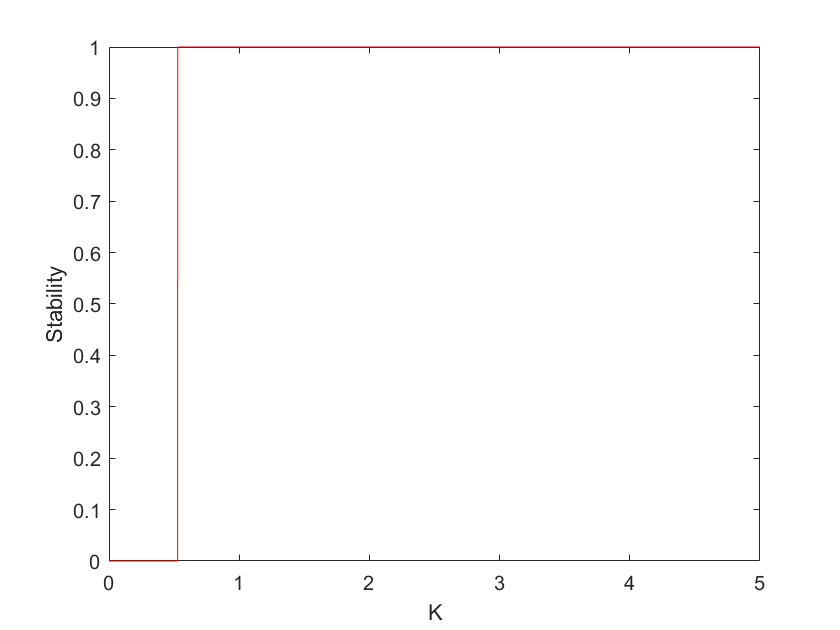

k=1e-3:1e-3:5;
y=zeros(size(k));

for i =1:length(k)
    y(i)=rhc([1,3*k(i),k(i)+2,4],0);
end
figure;
plot(k,y,"r-")
xlabel("K");
ylabel("Stability");

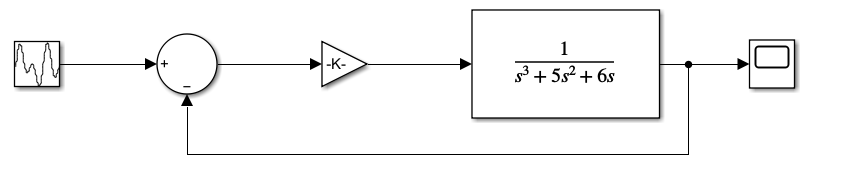

stable response on k >0.527

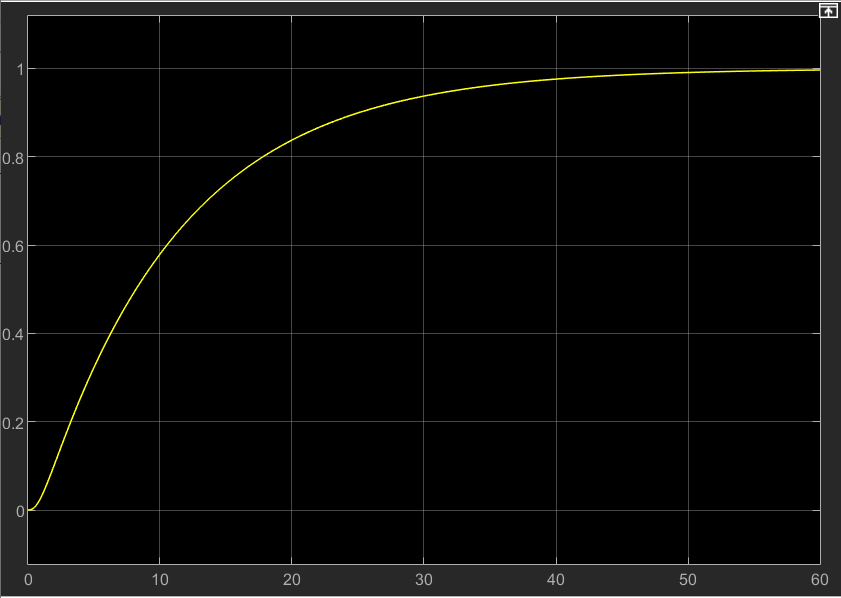

# QS. 6

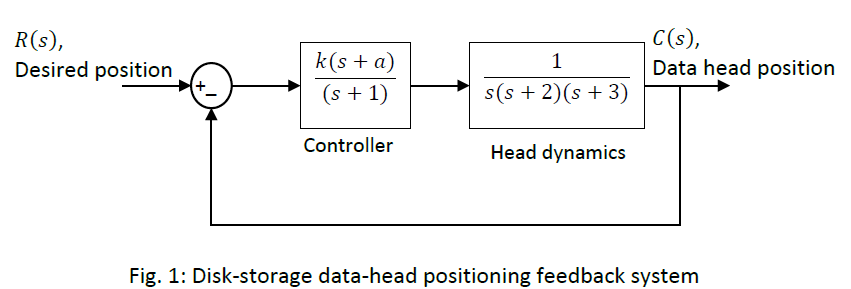

$0<K\leq60$; $0\leq a\leq \frac{10}{k}+\frac{3}{2}-\frac{k}{36}$; The system is stable

$K=60$; $a=0$; The system is marginally stable with pole at 0

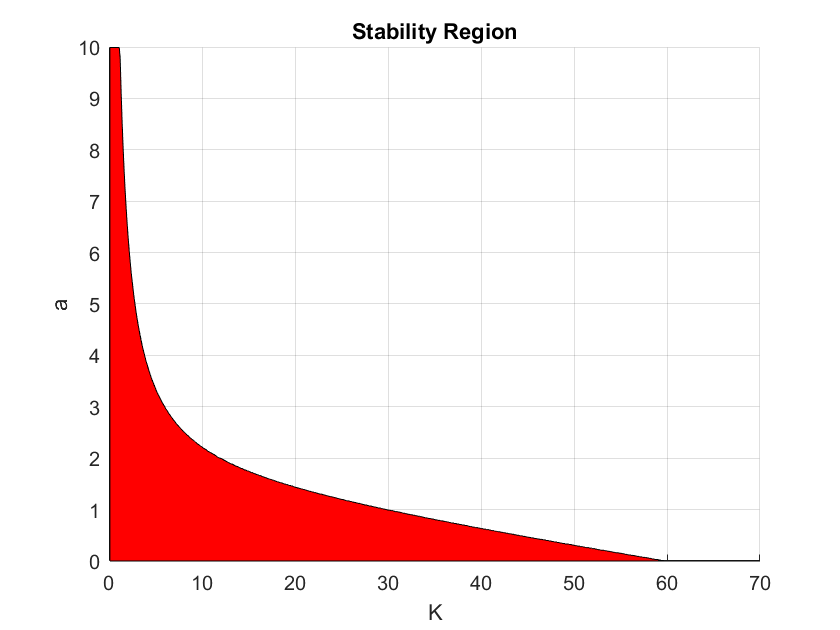

k=0.1:0.1:70;
a=0:0.01:10;
y=zeros(size(k));

for i=1:length(k)
    for j=1:length(a)-1
        c=rhc([1,6,11,6+k(i),k(i)*a(j)],0);
        b=rhc([1,6,11,6+k(i),k(i)*a(j+1)],0);
        if(c~=b)||(b==1 && j==length(a)-1)
            y(i)=a(j);
        end
    end
end

figure;
patch([k,fliplr(k)],[y,zeros(size(y))],'r')
xlabel("K");
ylabel("a");
title("Stability Region");
grid on

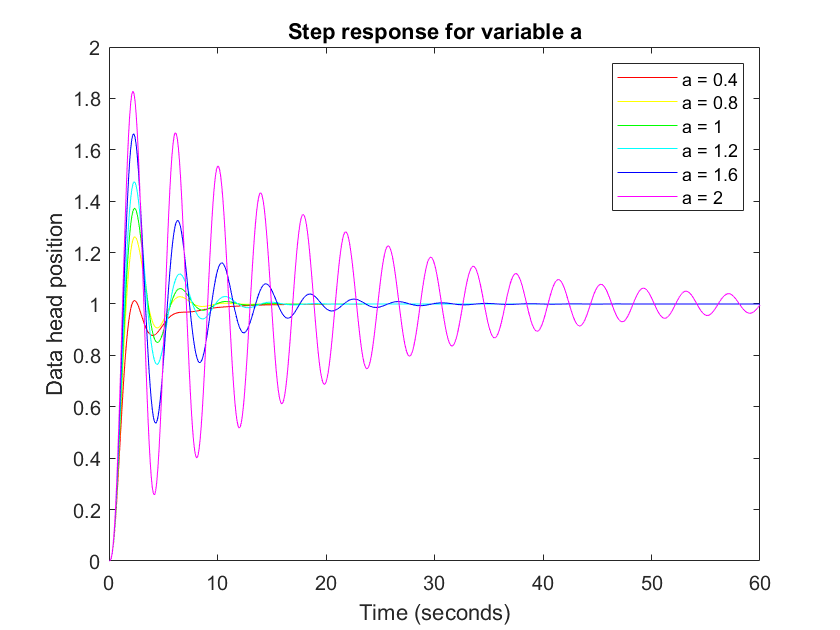

A=[0.4,0.8,1.0,1.2,1.6,2.0];
CM=hsv(6);
figure;

for i=1:6
    model6a=A(i);
    out=sim("model_6.slx");
    plot(out.c,"Color",CM(i,:),"DisplayName",strcat("a = ",num2str(model6a)));
    hold on
end

hold off
legend
ylabel("Data head position");
title("Step response for variable a");

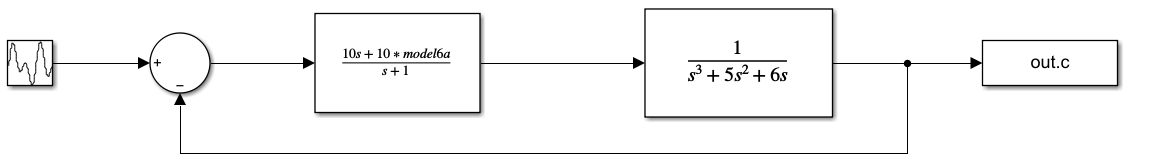

Reducing the value of a, reduces the overshoot and oscillation

For higher value of a, the system reaches the steady state value faster 

but it oscillates for long time

# QS.7

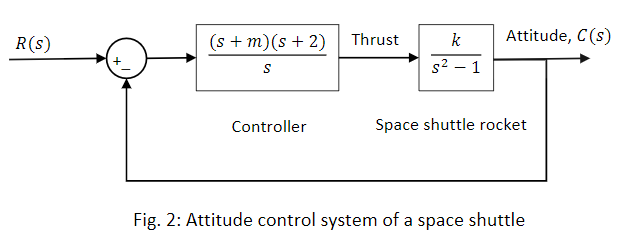

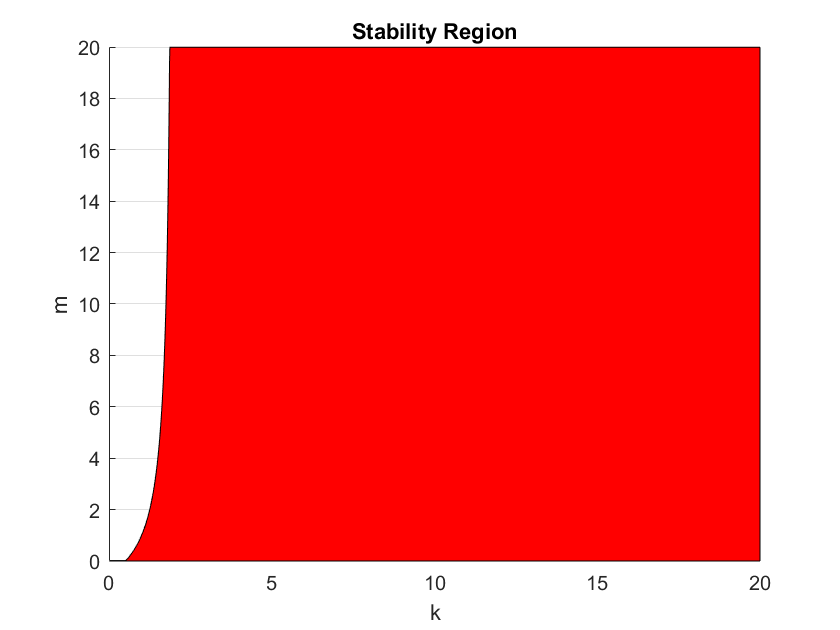

k=0.01:0.01:20;
m=0:0.01:20;
y=zeros(size(k));

for i=1:length(k)
    for j=1:length(m)-1
        a=rhc([1,k(i),k(i)*(m(j)+2)-1,2*k(i)*m(j)],0);
        b=rhc([1,k(i),k(i)*(m(j+1)+2)-1,2*k(i)*m(j+1)],0);
        if(a~=b)||(b==1 && j==length(m)-1)
            y(i)=m(j);
        end
    end
end

figure;
patch([k,fliplr(k)],[y,zeros(size(y))],'r')
xlabel("k");
ylabel("m");
title("Stability Region");
grid on

Stability region:

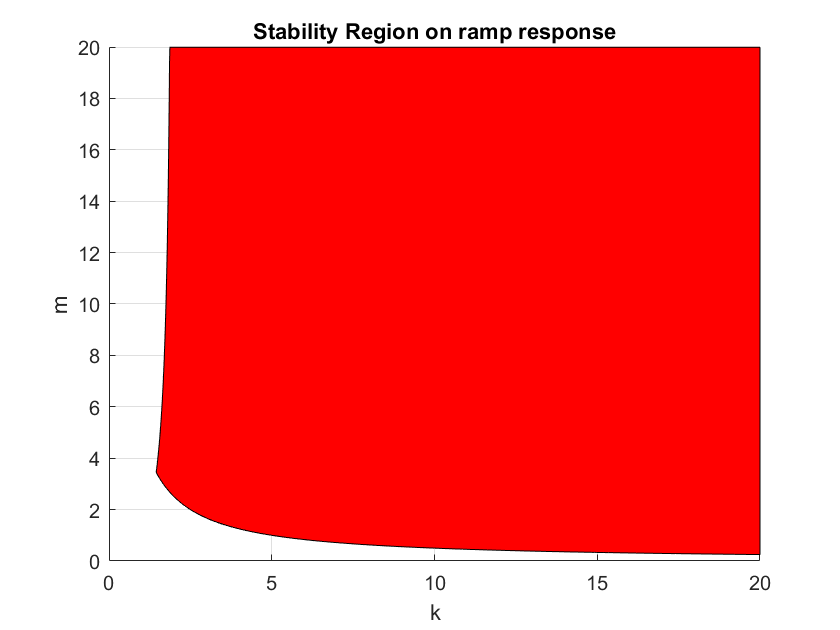

y1=5./k;
Li=(y>=y1);
figure;

patch([k(Li),fliplr(k(Li))],[y(Li),fliplr(y1(Li))],'r');
xlabel("k");
ylabel("m");
grid on
title("Stability Region on ramp response");

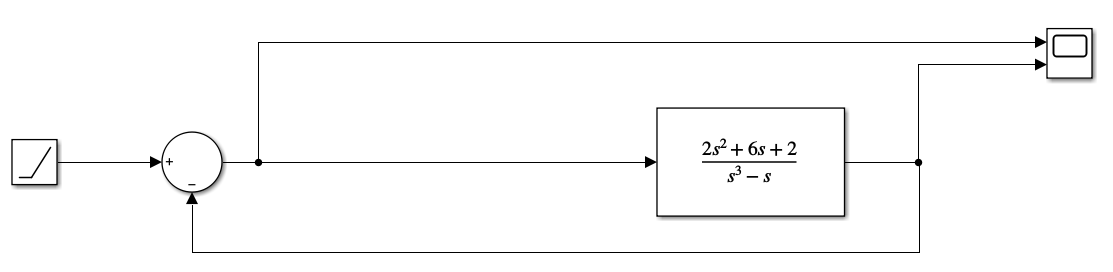

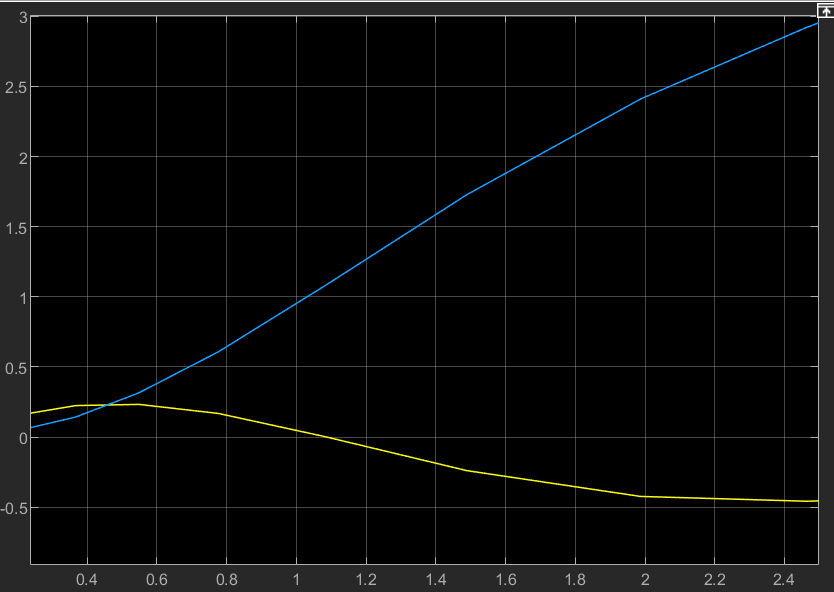

# QS. 8

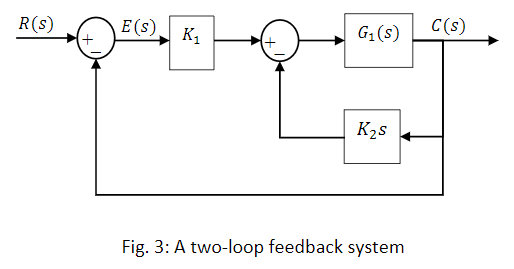

At K2=1, value of K1 vaaries in the range of 0<K1<54

At K1=54, the system is marginally stable i.e. oscillates

Frequency of Oscillation will be 3rad/sec.

System becomes unstable when K1>54

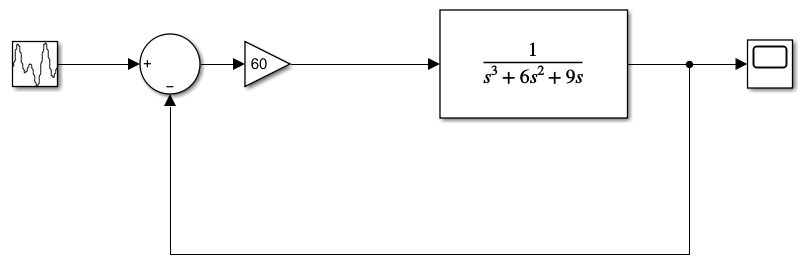

K1=40, stable

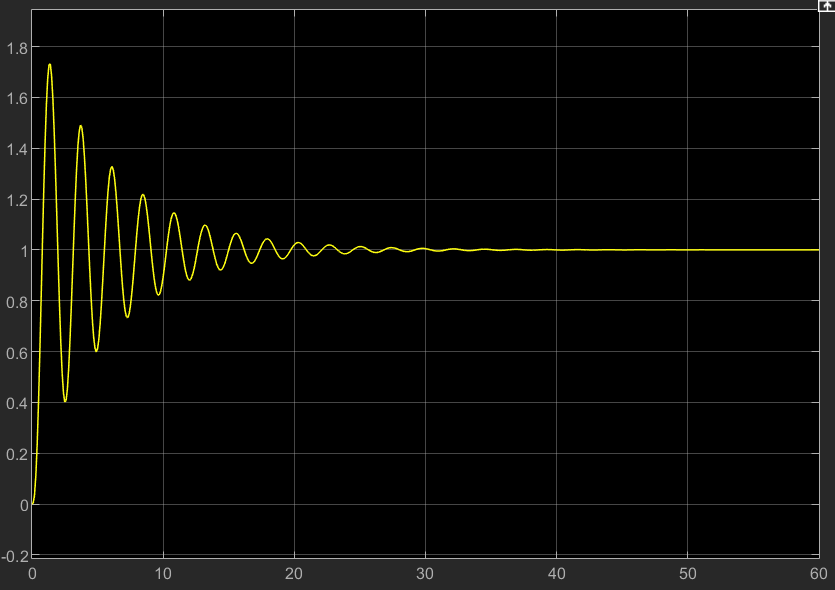

K1=54, marginally stable

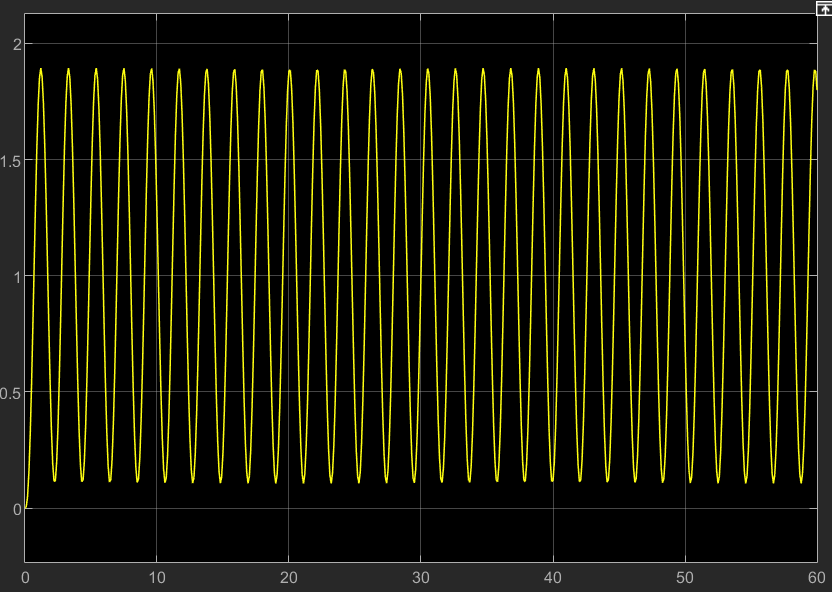

K1=60, unstable

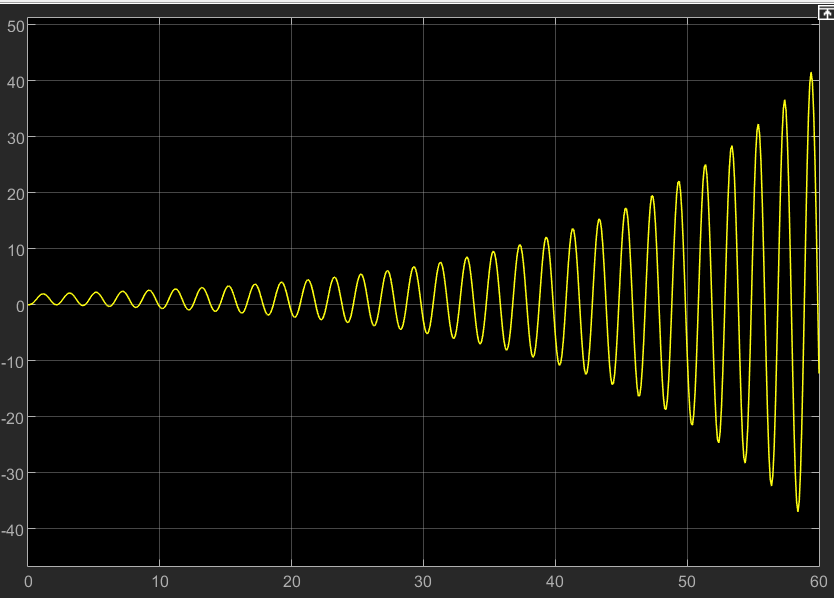

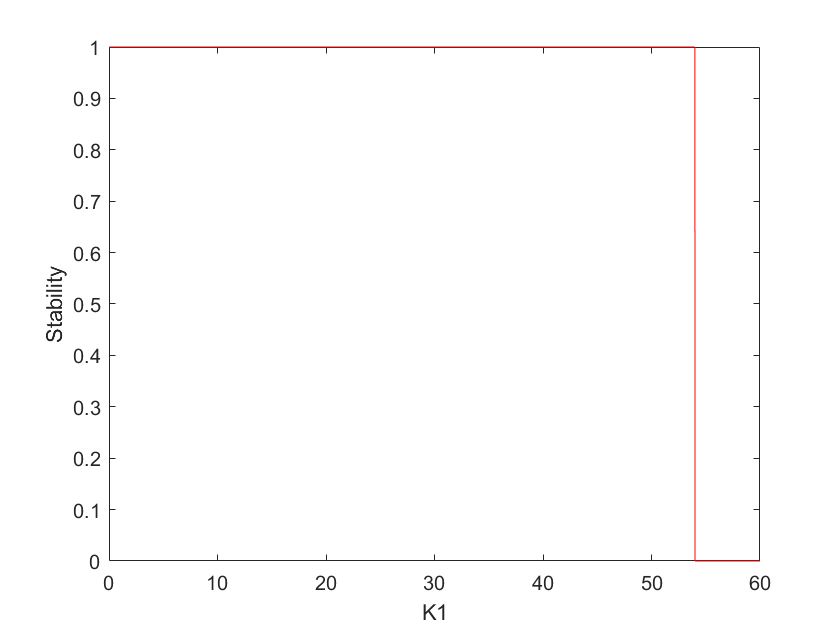

%a,b

k1=1e-2:1e-2:60;
y=zeros(size(k));

for i =1:length(k1)
    y(i)=rhc([1,6,9,k1(i)],0);
end

figure;
plot(k1,y,"r-")
xlabel("K1");
ylabel("Stability");

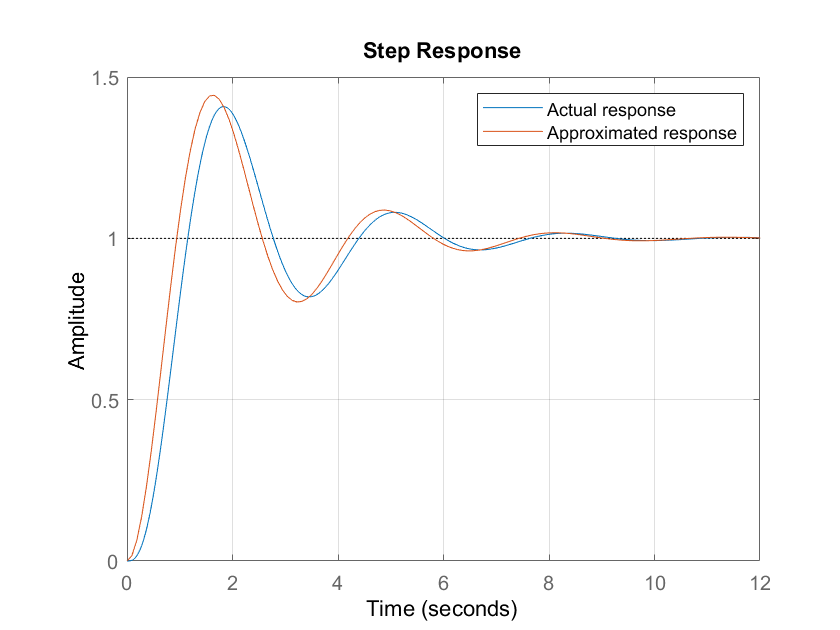

%c

tf1=tf(20,[1,6,9,20]);
tf2=tf(4,[1,1,4]);
step(tf1,tf2);
legend("Actual response","Approximated response")
grid on

# QS. 9

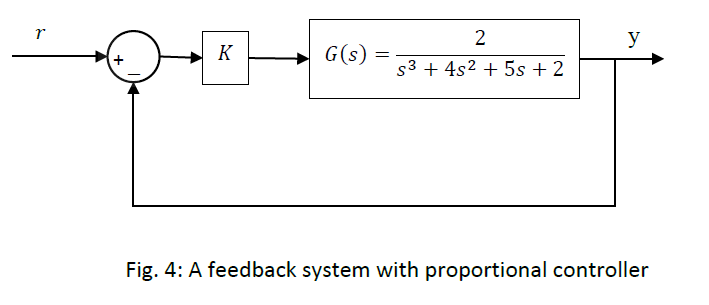

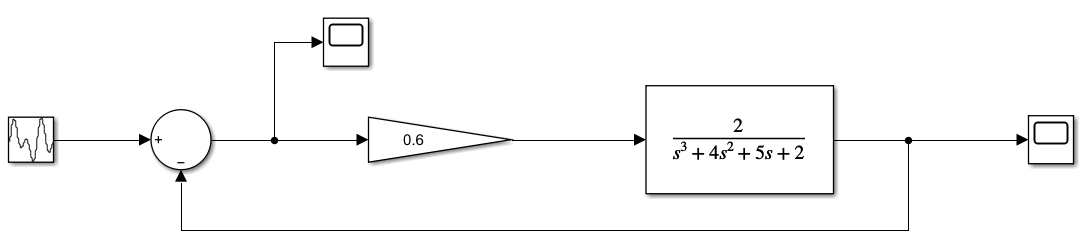

Y curve(output)

Gain=0.1, 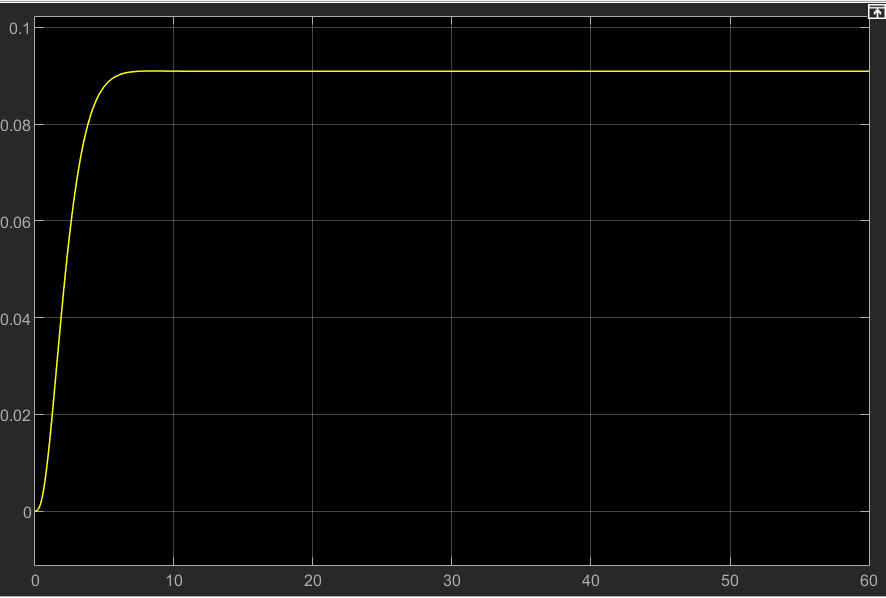

Gain=0.6,  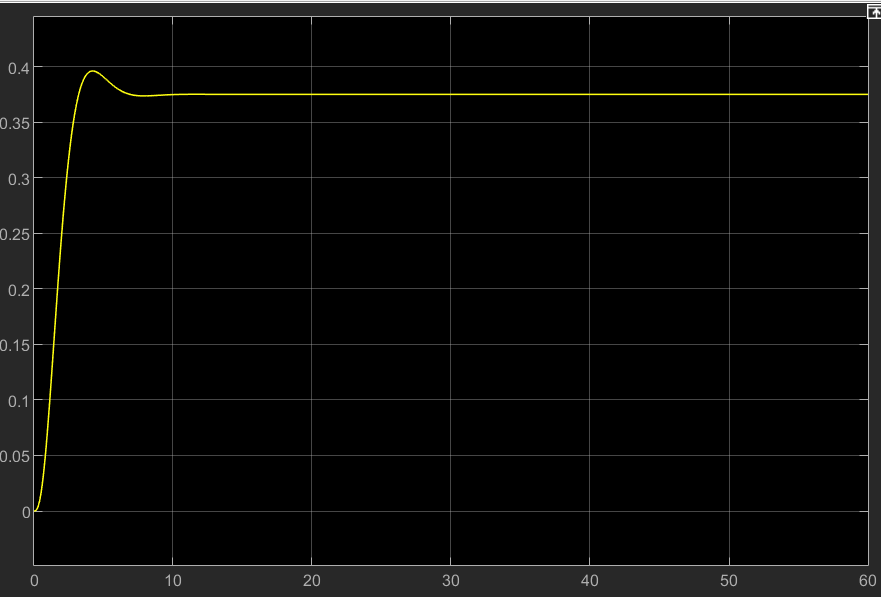

Gain=0.9, 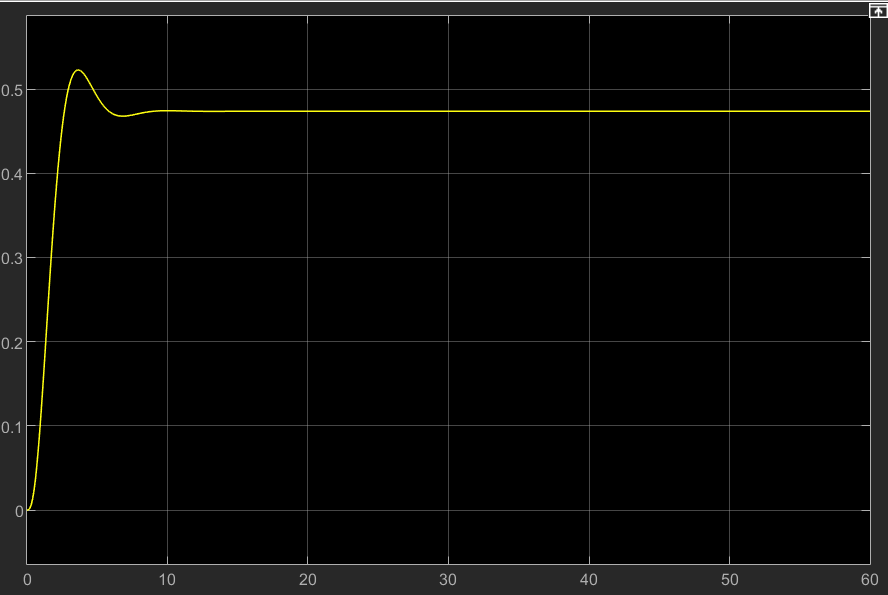

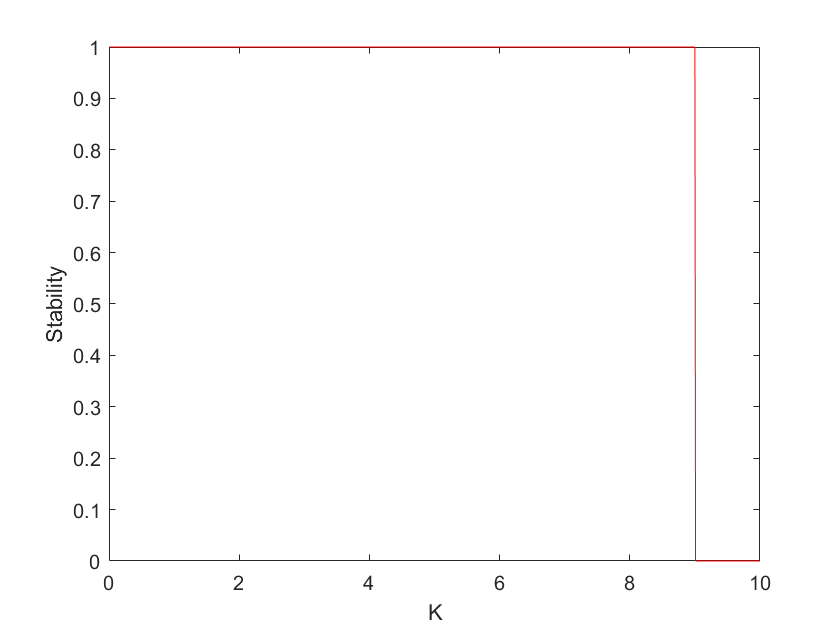

k=0:0.01:10;
y=zeros(size(k));

for i =1:length(k)
y(i)=rhc([1,4,5,2+2*k(i)],0);
end

figure;
plot(k,y,"r-")
xlabel("K");
ylabel("Stability");

plot $e_{ss}$ vs $K$ graph.

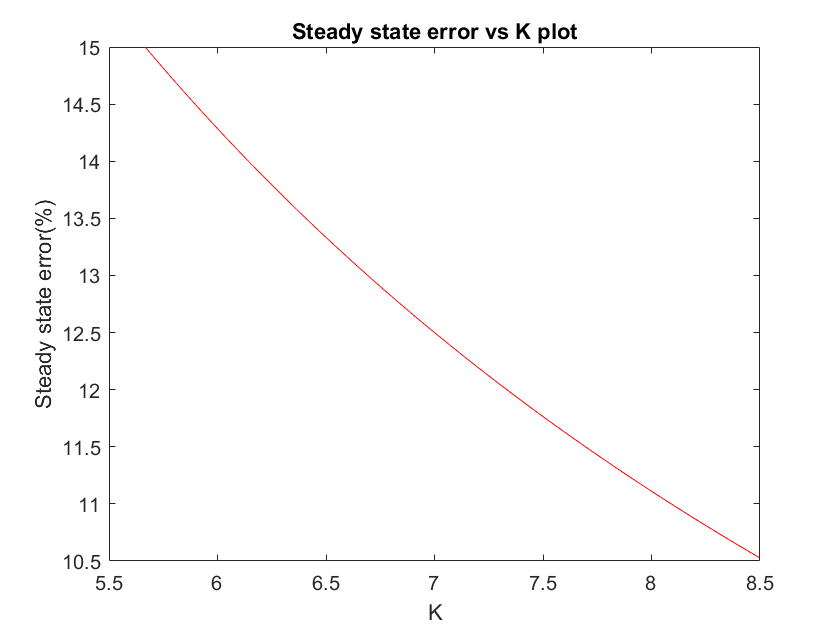

% The error gradually decreases till. 
% Then the system becomes unstable

K=17/3:1e-2:8.5;
error=zeros(size(K));

for i=1:length(K)
    [y,t]=step(tf(2*K(i),[1,4,5,2+2*K(i)]),500);
    error(i)=100*abs(1-y(end));
end

figure;
plot(K,error,'r');
xlabel("K");
ylabel("Steady state error(%)");
title("Steady state error vs K plot");

# QS. 10

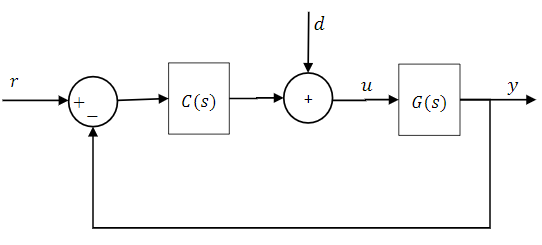

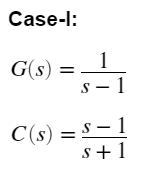

r-to-y and r-to-u:

Model:

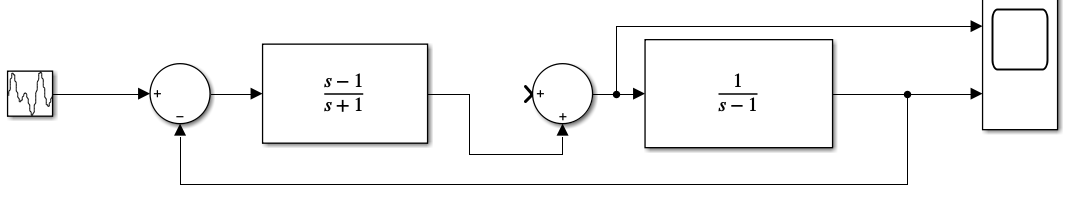

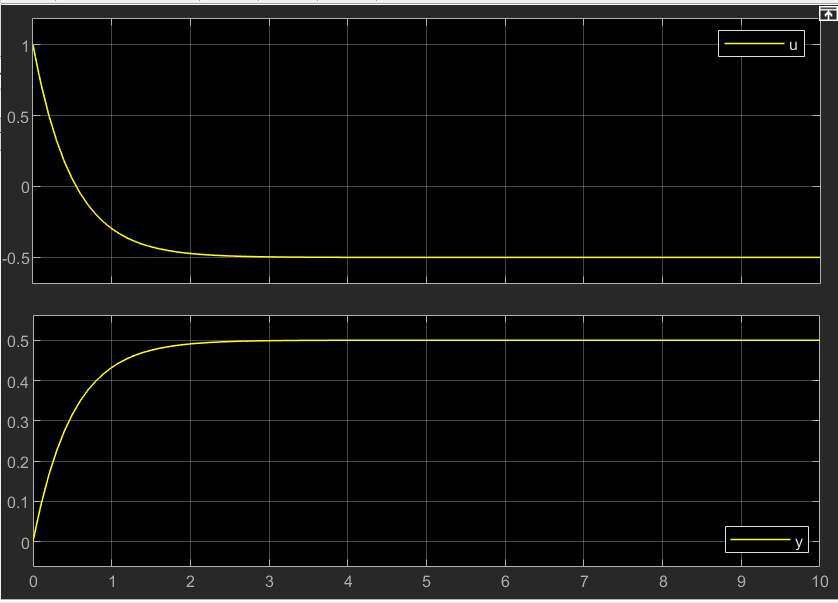

d-to-y and d-to-u:

Model:

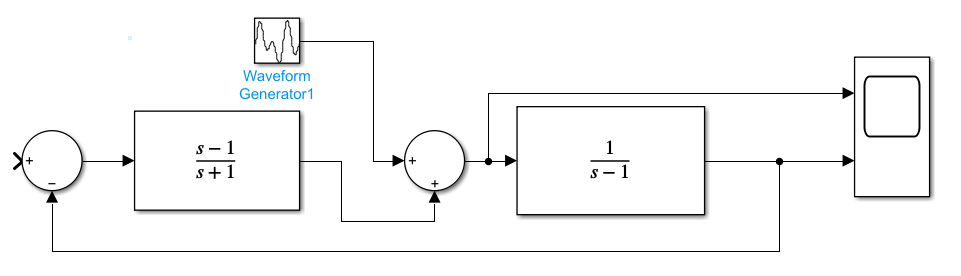

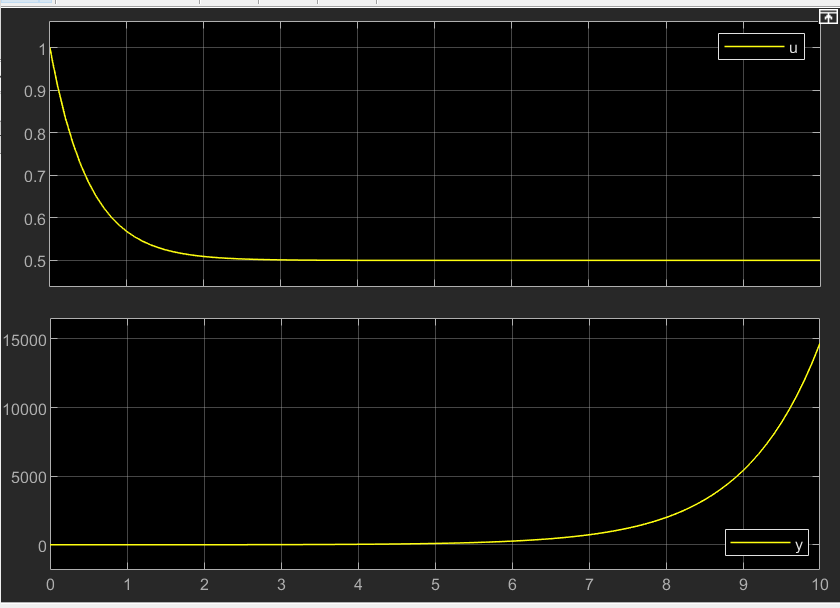

With d as disturbance in system, the system behaves uncontrollably,

as u(t) is unstable for d-to-u.

So for even a little disturbance in system, output at u will reach saturation, 

changing the system output y. 

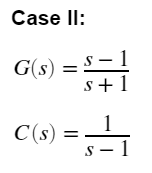

r-to-y and r-to-u:

Model:

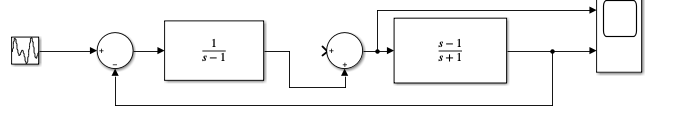

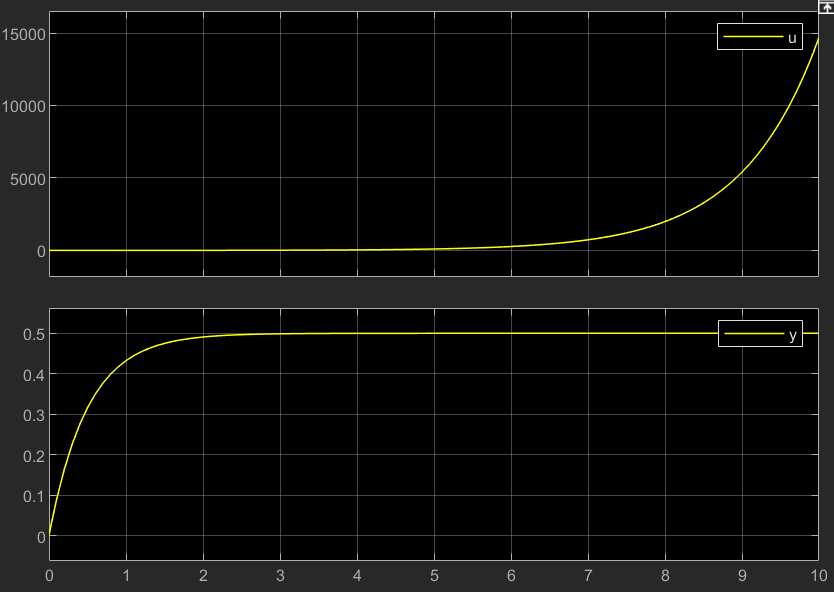

d-to-y and d-to-u:

Model:

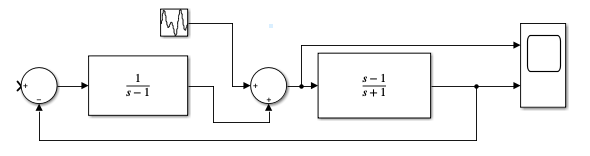

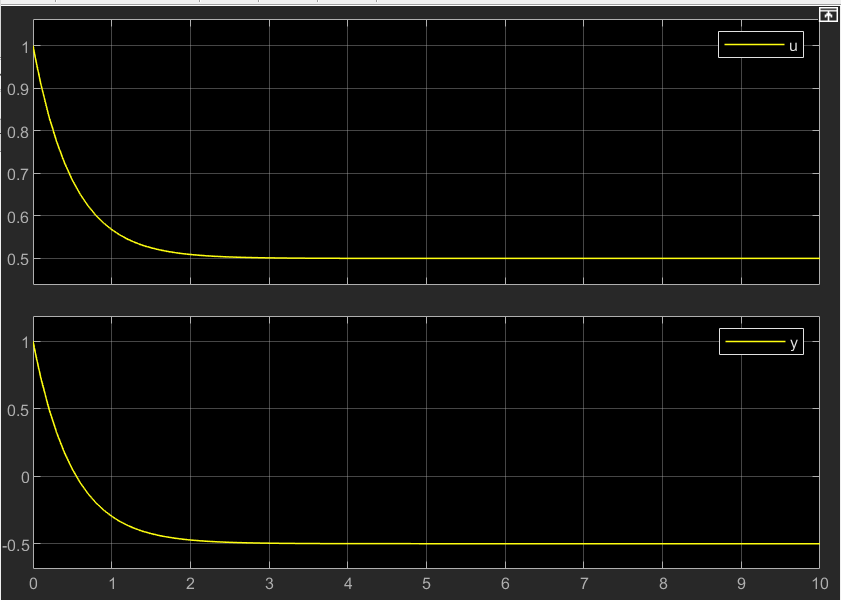

Disturbance is controlled, as both output d-to-u and d-to-y are stable. 

But the output response at u for reference input is uncontrollable, 

which will reach saturation faster and change the output y.

function y=rhc(coeffVector,x)
ceoffLength = length(coeffVector);
rhTableColumn = round(ceoffLength/2);
rhTable = zeros(ceoffLength,rhTableColumn);
rhTable(1,:) = coeffVector(1,1:2:ceoffLength);
if (rem(ceoffLength,2) ~= 0)
    rhTable(2,1:rhTableColumn - 1) = coeffVector(1,2:2:ceoffLength);
else
    rhTable(2,:) = coeffVector(1,2:2:ceoffLength);
end
epss=0.0001;
for i = 3:ceoffLength
    if rhTable(i-1,:) == 0
        order = (ceoffLength - i);
        cnt1 = 0;
        cnt2 = 1;
        for j = 1:rhTableColumn - 1
            rhTable(i-1,j) = (order - cnt1) * rhTable(i-2,cnt2);
            cnt2 = cnt2 + 1;
            cnt1 = cnt1 + 2;
        end
    end
    for j = 1:rhTableColumn - 1
        firstElemUpperRow = rhTable(i-1,1);
        rhTable(i,j) = ((rhTable(i-1,1) * rhTable(i-2,j+1))-(rhTable(i-2,1) * rhTable(i-1,j+1))) / firstElemUpperRow;
    end
    if rhTable(i,1) == 0
        rhTable(i,1) = epss;
    end
end
unstablePoles = 0;
for i = 1:ceoffLength - 1
    if sign(rhTable(i,1)) * sign(rhTable(i+1,1)) == -1
        unstablePoles = unstablePoles + 1;
    end
end
if x==1
    fprintf('\n Routh-Hurwitz Table:\n')
    rhTable %#ok<NOPRT>
end
if unstablePoles == 0
    y=1;
else
    y=0;
end
end